clear all; close all;

## original signal:


[y,Fs] = audioread("Vuvuzela.wav");


## First second signal

%required to seperate the vuvuzela sound from the humen sound.
firstsec=[4*Fs 5.5*Fs];
[yn,fs] = audioread("Vuvuzela.wav",firstsec);


## Spectroom analysis:

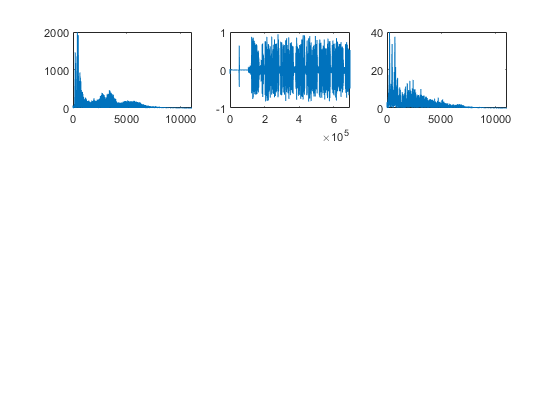

L=length(y);
NFFT=2^(nextpow2(L))%claculate the closest next power of 2 to the signal length, required for the FFT algorythm;
NFFT2=2^(nextpow2(length(yn)))%claculate the closest next power of 2 to the signal length, required for the FFT algorythm;
Y_FFTimg=fft(y,NFFT);
Y_FFT=abs(fft(y,NFFT))% Calculate the DFT of the signal (Amplitude as function of frequency) using FFT ,require for finding the unwanted frequencies;
Y_FFT2=abs(fft(yn,NFFT2))% Calculate the DFT of the signal (Amplitude as function of frequency) using FFT ,require for finding the unwanted frequencies;
f=(Fs).*(0:(NFFT/2-1))/NFFT; %xaxis for ploting
f2=(fs).*(0:(NFFT2/2-1))/NFFT2;%xaxis for ploting.
subplot(3,3,1)
plot(f,Y_FFT(1:length(f)));
subplot(3,3,2)
plot(y)
subplot(3,3,3)
plot(f2,Y_FFT2(1:length(f2)));

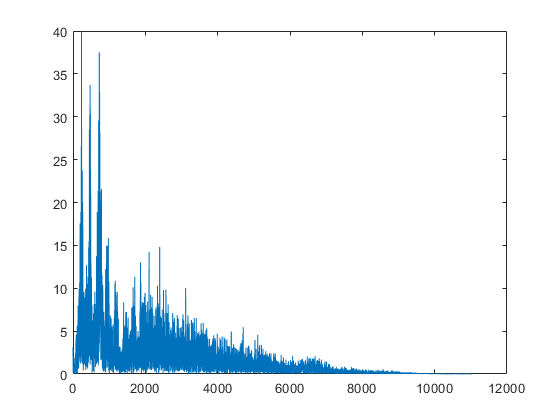

figure(2)

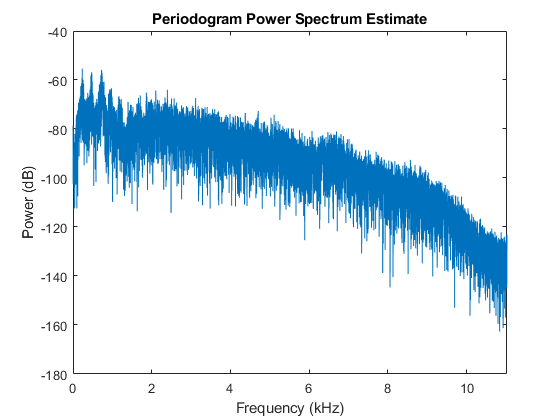

periodogram(yn,[],NFFT2,fs,'power');
grid;

## Filtering:


fc1=230;
fc2=473.7;

%fc3=725;
%fc4=925;
%fc5=1180;
fc3=925;
fc4=1180;
fc5=2397;

r1=0.99;
r2=0.96;
r3=0.94;
r4=0.92;
r5=0.90;

theta01=(2*pi*fc1)/fs;
theta02=(2*pi*fc2)/fs;
theta03=(2*pi*fc3)/fs;
theta04=(2*pi*fc4)/fs;
theta05=(2*pi*fc5)/fs;

b1=-2*cos(theta01);
a1=-2*r1*cos(theta01);

b2=-2*cos(theta02);
a2=-2*r2*cos(theta02);

b3=-2*cos(theta03);
a3=-2*r3*cos(theta03);

b4=-2*cos(theta04);
a4=-2*r4*cos(theta04);

b5=-2*cos(theta05);
a5=-2*r5*cos(theta05);

b11=[1,b1,1]

b11 =     1.0000   -1.9957    1.0000


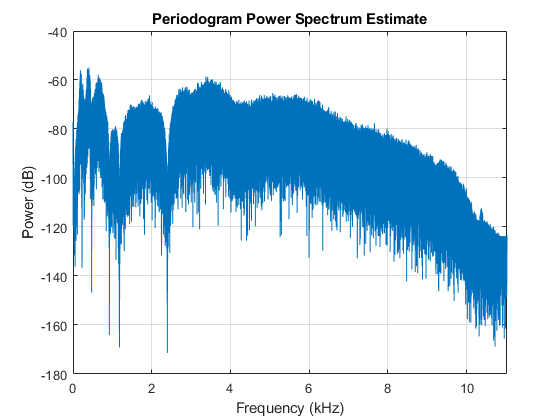

a11=[1,a1,(r1)^2];
H1=impz(b11,a11);


b12=[1,b2,1];
a12=[1,a2,(r2)^2];
H2=impz(b12,a12);
%fvtool(b12,a12);
%x2=conv(x1,H2,'same');


b13=[1,b3,1];
a13=[1,a3,(r3)^2];
H3=impz(b13,a13);



b14=[1,b4,1];
a14=[1,a4,(r4)^2];
H4=impz(b14,a14);



b15=[1,b5,1];
a15=[1,a5,(r5)^2];
H5=impz(b15,a15);



h1=conv(H1,H2);
h2=conv(H3,h1);
h3=conv(H4,h2);
hfinal=conv(H5,h3);

fvtool(hfinal);
xfinal=conv(y,hfinal);

periodogram(xfinal,[],NFFT,Fs,'power')

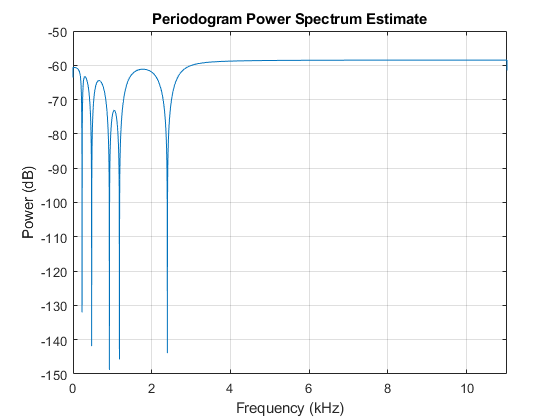

periodogram(hfinal,[],NFFT,Fs,'power')

## improvement by equlizer(amplify the chosen frequencies after filter):


%play with r:
r=0.4;

a=[1,-2*r*cos(theta03),r^2];
  H6=impz(-1,16);
  periodogram(H6,[],NFFT,Fs,'power')

Error using computeperiodogram>validateinputs (line 196)
The input must be either a vector or two-dimensional matrix.

Error in computeperiodogram (line 61)
[x1,~,y,is2sig,win1] = validateinputs(x,win,nfft);

Error in 

xfinal=conv(xfinal,H6);